% set up
% this is a naive case:
% our reference is a sin wave and noise is randomly generated
step = 0.1;
endtime = 30; % start time is zero no need to define
T = 0:step:endtime;
Reference =sin(T);
noise = rand(1,endtime/step+1)-0.5;
Real = Reference+noise;
Error = Reference - Real;
Kp = 0.3;
Kd = 0.02;
Ki = 0.2;

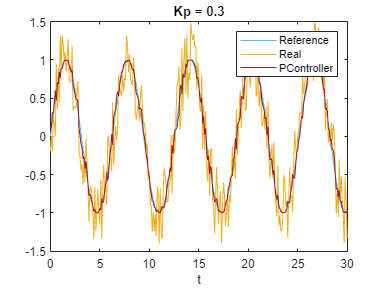

% P controller
Gp = Kp * Error;
POut = sin(Gp+T);
% plot
figure
plot(T,Reference,'color',"#4DBEEE")
hold on
plot(T,Real,'color',"#EDB120")
hold on
plot(T,POut,'color',"#A2142F")
legend('Reference','Real','PController')
title("Kp = " + num2str(Kp))
xlabel('t')

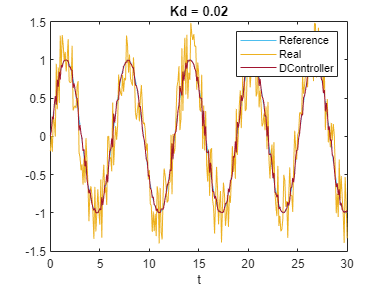

% D controller
De = diff(Error)/step;
De = [0, De]; %pad with zero to fit the dimension
Gd = Kd * De;
DOut = sin(T+Gd);
% plot
figure
plot(T,Reference,'color',"#4DBEEE")
hold on
plot(T,Real,'color',"#EDB120")
hold on
plot(T,DOut,'color',"#A2142F")
legend('Reference','Real','DController')
title("Kd = " + num2str(Kd))
xlabel('t')

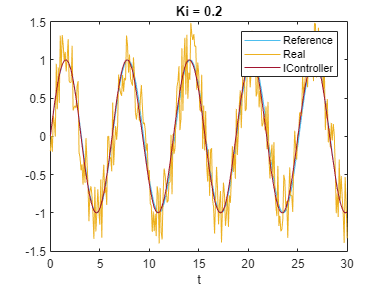

% I controller Homework answer:
Ie = TrepozoidalIntegration_(Error,T);
Gi = Ki * Ie;
IOut = sin(T+Gi);
%plot
figure
plot(T,Reference,'color',"#4DBEEE")
hold on
plot(T,Real,'color',"#EDB120")
hold on
plot(T,IOut,'color',"#A2142F")
legend('Reference','Real','IController')
title("Ki = " + num2str(Ki))
xlabel('t')

% PID
PIDOut = sin(T+Gi+Gd+Gp)

PIDOut =     0.0614    0.1152    0.3828    0.2436    0.4972    0.6613    0.3263    0.8100    0.6243    0.9054    0.6531    0.9347    0.8482    0.9553    0.9929    0.9928    0.9913    0.9960    0.9961    0.8736    0.8786    0.8410    0.9135    0.5208    0.6100    0.5464    0.4653    0.5379    0.4547   -0.0856   -0.0146   -0.1592   -0.1647   -0.3800   -0.2358   -0.5121   -0.2453   -0.5507   -0.6891   -0.8542   -0.7270   -0.8038   -0.8865   -0.9571   -0.9971   -0.9242   -0.9908   -0.9999   -1.0000   -0.9558


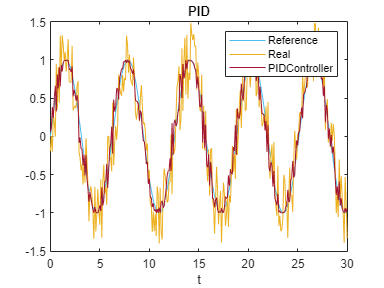

%plot
figure
plot(T,Reference,'color',"#4DBEEE")
hold on
plot(T,Real,'color',"#EDB120")
hold on
plot(T,PIDOut,'color',"#A2142F")
legend('Reference','Real','PIDController')
title("PID")
xlabel('t')

% PI
PIOut = sin(T+Gi+Gp)

PIOut =     0.0614    0.1354    0.3257    0.3158    0.4649    0.6189    0.4847    0.7238    0.6953    0.8554    0.7679    0.8971    0.8868    0.9450    0.9863    0.9952    0.9968    0.9923    0.9899    0.9196    0.8768    0.8350    0.8655    0.6475    0.5919    0.5302    0.4566    0.4732    0.4261    0.0811   -0.0199   -0.1465   -0.1999   -0.3489   -0.3207   -0.4728   -0.3739   -0.5162   -0.6555   -0.8087   -0.7860   -0.8197   -0.8811   -0.9455   -0.9905   -0.9688   -0.9998   -0.9992   -0.9988   -0.9715


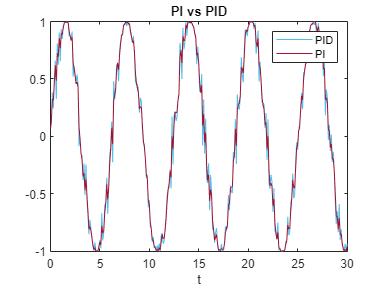

%plot
figure
plot(T,PIDOut,'color',"#4DBEEE")
hold on
plot(T,PIOut,'color',"#A2142F")
legend('PID','PI')
title("PI vs PID")
xlabel('t')